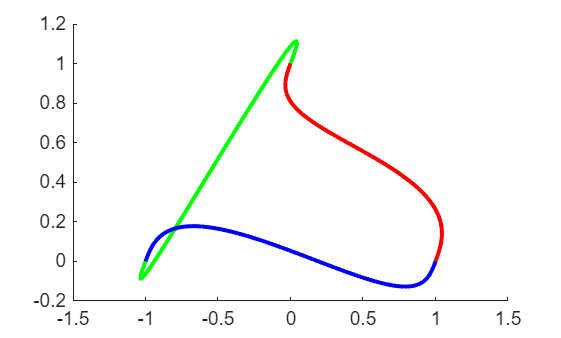

p = [1 0 -1;0 1 0];

dp = [0.5 0.5 0.5;1 1 1];

ddp = [0.5 0.5 0.5;1 1 1];

f = PathPlanning(p,dp,ddp);

s = 0:0.01:1;
f_ = zeros(2,3,length(s));
for i = 1:length(s)
    f_(:,:,i) = f(s(i));
end

x1 = f_(1,1,:);
y1 = f_(2,1,:);

x2 = f_(1,2,:);
y2 = f_(2,2,:);

x3 = f_(1,3,:);
y3 = f_(2,3,:);
hold on
plot(x1(:),y1(:),'Color','r','LineWidth', 2)
plot(x2(:),y2(:),'Color','g','LineWidth', 2)
plot(x3(:),y3(:),'Color','b','LineWidth', 2)